## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6S_Drive = [50 35 20 35]*NS_L6/1e3 * StimulusFac;
L6C_Drive = [50 35 20 35]*NC_L6/1e3 * StimulusFac;
L6I_Drive = [50 35 20 35]*NI_L6/1e3 * StimulusFac;

rE_L6_Drive = [L6S_Drive(OD_S),L6C_Drive(OD_C)]';
rI_L6_Drive = L6I_Drive(OD_I)';


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
          'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
        FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 9.0491

FrECNow = 33.9852

FrINow = 61.7112

Elapsed time is 2.267810 seconds.


SampleInd = 3

FrESNow = 8.1745

FrECNow = 53.0741

FrINow = 75.5856

Elapsed time is 4.027864 seconds.


SampleInd = 4

FrESNow = 7.2307

FrECNow = 26.1284

FrINow = 56.9129

Elapsed time is 6.189925 seconds.


SampleInd = 5

FrESNow = 8.7726

FrECNow = 63.9407

FrINow = 85.1636

Elapsed time is 8.094231 seconds.


SampleInd = 6

FrESNow = 6.6118

FrECNow = 30.2370

FrINow = 60.5689

Elapsed time is 10.244149 seconds.


SampleInd = 7

FrESNow = 7.8475

FrECNow = 41.4494

FrINow = 68.5490

Elapsed time is 11.864195 seconds.


SampleInd = 8

FrESNow = 7.8672

FrECNow = 46.6840

FrINow = 72.3482

Elapsed time is 14.245619 seconds.


SampleInd = 9

FrESNow = 7.5391

FrECNow = 42.6864

FrINow = 69.9133

Elapsed time is 15.932359 seconds.


SampleInd = 10

FrESNow = 7.8584

FrECNow = 45.8790

FrINow = 72.4246

Elapsed time is 18.397263 seconds.


SampleInd = 11

FrESNow = 7.4952

FrECNow = 41.7926

FrINow = 69.6543

Elapsed time is 20.123884 seconds.


SampleInd = 12

FrESNow = 7.4820

FrECNow = 42.0296

FrINow = 69.1849

Elapsed time is 22.552380 seconds.


SampleInd = 13

FrESNow = 7.6949

FrECNow = 43.1531

FrINow = 70.5746

Elapsed time is 24.269302 seconds.


SampleInd = 14

FrESNow = 7.7114

FrECNow = 42.3704

FrINow = 69.9665

Elapsed time is 26.692858 seconds.


SampleInd = 15

FrESNow = 7.4754

FrECNow = 41.5037

FrINow = 68.9005

Elapsed time is 28.272285 seconds.


SampleInd = 16

FrESNow = 7.6796

FrECNow = 45.4049

FrINow = 71.7424

Elapsed time is 30.644347 seconds.


SampleInd = 17

FrESNow = 7.6894

FrECNow = 46.3728

FrINow = 73.0975

Elapsed time is 32.342436 seconds.


SampleInd = 18

FrESNow = 7.4030

FrECNow = 39.3975

FrINow = 67.6888

Elapsed time is 34.769563 seconds.


SampleInd = 19

FrESNow = 7.5852

FrECNow = 41.1556

FrINow = 68.5536

Elapsed time is 36.400258 seconds.


SampleInd = 20

FrESNow = 7.9813

FrECNow = 51.2815

FrINow = 76.5661

Elapsed time is 38.956952 seconds.


SampleInd = 21

FrESNow = 7.1221

FrECNow = 40.3136

FrINow = 68.4495

Elapsed time is 40.550881 seconds.


Elapsed time is 40.551661 seconds.


SampleInd = 22

FrESNow = 7.4667

FrECNow = 39.8667

FrINow = 67.6471

Elapsed time is 2.476651 seconds.


SampleInd = 23

FrESNow = 7.9232

FrECNow = 44.4914

FrINow = 71.2290

Elapsed time is 4.260393 seconds.


SampleInd = 24

FrESNow = 7.5962

FrECNow = 45.0049

FrINow = 71.5921

Elapsed time is 6.767085 seconds.


SampleInd = 25

FrESNow = 7.6565

FrECNow = 42.2519

FrINow = 69.9179

Elapsed time is 8.432434 seconds.


SampleInd = 26

FrESNow = 7.4151

FrECNow = 41.3481

FrINow = 68.7270

Elapsed time is 10.856224 seconds.


SampleInd = 27

FrESNow = 7.8431

FrECNow = 43.9580

FrINow = 70.9585

Elapsed time is 12.588119 seconds.


SampleInd = 28

FrESNow = 7.4776

FrECNow = 40.6469

FrINow = 68.2067

Elapsed time is 14.897990 seconds.


SampleInd = 29

FrESNow = 7.7959

FrECNow = 48.3877

FrINow = 74.0664

Elapsed time is 16.600169 seconds.


SampleInd = 30

FrESNow = 7.7366

FrECNow = 48.1383

FrINow = 74.6514

Elapsed time is 19.024643 seconds.


SampleInd = 31

FrESNow = 7.0639

FrECNow = 31.6049

FrINow = 62.0419

Elapsed time is 20.509647 seconds.


SampleInd = 32

FrESNow = 8.2348

FrECNow = 55.3383

FrINow = 79.1768

Elapsed time is 23.020648 seconds.


SampleInd = 33

FrESNow = 6.3331

FrECNow = 29.8123

FrINow = 59.5907

Elapsed time is 24.457809 seconds.


SampleInd = 34

FrESNow = 8.0735

FrECNow = 50.4000

FrINow = 75.5139

Elapsed time is 26.938240 seconds.


SampleInd = 35

FrESNow = 7.4239

FrECNow = 46.3432

FrINow = 72.7714

Elapsed time is 28.638197 seconds.


SampleInd = 36

FrESNow = 7.2713

FrECNow = 34.9235

FrINow = 64.4005

Elapsed time is 30.947742 seconds.


SampleInd = 37

FrESNow = 7.7344

FrECNow = 48.1654

FrINow = 73.3680

Elapsed time is 32.729791 seconds.


SampleInd = 38

FrESNow = 7.4348

FrECNow = 41.5284

FrINow = 69.0184

Elapsed time is 35.078596 seconds.


SampleInd = 39

FrESNow = 7.5918

FrECNow = 45.1037

FrINow = 71.5505

Elapsed time is 36.792051 seconds.


SampleInd = 40

FrESNow = 7.5512

FrECNow = 43.8741

FrINow = 71.1851

Elapsed time is 39.234733 seconds.


SampleInd = 41

FrESNow = 7.5303

FrECNow = 39.4815

FrINow = 67.6309

Elapsed time is 40.942916 seconds.


Elapsed time is 40.943721 seconds.


SampleInd = 42

FrESNow = 7.9067

FrECNow = 49.5111

FrINow = 74.8873

Elapsed time is 2.426143 seconds.


SampleInd = 43

FrESNow = 7.2582

FrECNow = 39.9012

FrINow = 68.0495

Elapsed time is 4.049220 seconds.


SampleInd = 44

FrESNow = 7.9243

FrECNow = 47.4568

FrINow = 73.6709

Elapsed time is 6.430450 seconds.


SampleInd = 45

FrESNow = 7.5248

FrECNow = 50.0074

FrINow = 75.5093

Elapsed time is 8.197867 seconds.


SampleInd = 46

FrESNow = 7.1484

FrECNow = 31.3432

FrINow = 61.8014

Elapsed time is 10.369932 seconds.


SampleInd = 47

FrESNow = 8.0274

FrECNow = 53.5457

FrINow = 77.4934

Elapsed time is 12.164727 seconds.


SampleInd = 48

FrESNow = 6.7731

FrECNow = 31.3086

FrINow = 61.2094

Elapsed time is 14.432523 seconds.


SampleInd = 49

FrESNow = 8.1756

FrECNow = 52.1975

FrINow = 76.9869

Elapsed time is 16.278750 seconds.


SampleInd = 50

FrESNow = 7.3800

FrECNow = 41.8346

FrINow = 69.8324

Elapsed time is 18.752192 seconds.


SampleInd = 51

FrESNow = 7.7684

FrECNow = 42.9901

FrINow = 70.8544

Elapsed time is 20.525720 seconds.


SampleInd = 52

FrESNow = 7.5040

FrECNow = 43.3383

FrINow = 70.1399

Elapsed time is 22.846929 seconds.


SampleInd = 53

FrESNow = 7.5117

FrECNow = 41.7926

FrINow = 69.0138

Elapsed time is 24.476479 seconds.


SampleInd = 54

FrESNow = 7.5588

FrECNow = 38.7235

FrINow = 66.9603

Elapsed time is 26.736479 seconds.


SampleInd = 55

FrESNow = 7.5863

FrECNow = 46.5136

FrINow = 72.2673

Elapsed time is 28.458504 seconds.


SampleInd = 56

FrESNow = 7.8277

FrECNow = 42.9185

FrINow = 70.3110

Elapsed time is 30.849026 seconds.


SampleInd = 57

FrESNow = 7.7026

FrECNow = 47.0247

FrINow = 73.6062

Elapsed time is 32.572974 seconds.


SampleInd = 58

FrESNow = 7.3745

FrECNow = 41.1481

FrINow = 69.1201

Elapsed time is 34.954493 seconds.


SampleInd = 59

FrESNow = 7.5336

FrECNow = 41.8815

FrINow = 69.7607

Elapsed time is 36.647110 seconds.


SampleInd = 60

FrESNow = 7.5106

FrECNow = 41.5309

FrINow = 68.8218

Elapsed time is 38.987521 seconds.


SampleInd = 61

FrESNow = 7.8672

FrECNow = 46.3309

FrINow = 72.8223

Elapsed time is 40.649615 seconds.


Elapsed time is 40.650355 seconds.


SampleInd = 62

FrESNow = 7.1594

FrECNow = 39.3259

FrINow = 66.9141

Elapsed time is 2.329039 seconds.


SampleInd = 63

FrESNow = 7.6521

FrECNow = 42.8790

FrINow = 69.9642

Elapsed time is 4.017702 seconds.


SampleInd = 64

FrESNow = 7.4908

FrECNow = 45.3185

FrINow = 71.7216

Elapsed time is 6.351434 seconds.


SampleInd = 65

FrESNow = 7.7575

FrECNow = 42.6198

FrINow = 70.0728

Elapsed time is 8.118474 seconds.


SampleInd = 66

FrESNow = 7.9912

FrECNow = 49.1852

FrINow = 75.6689

Elapsed time is 10.596333 seconds.


SampleInd = 67

FrESNow = 6.9915

FrECNow = 38.2395

FrINow = 66.6250

Elapsed time is 12.205969 seconds.


SampleInd = 68

FrESNow = 7.6082

FrECNow = 39.5284

FrINow = 67.4552

Elapsed time is 14.482324 seconds.


SampleInd = 69

FrESNow = 7.8332

FrECNow = 47.5951

FrINow = 73.1391

Elapsed time is 16.163236 seconds.


SampleInd = 70

FrESNow = 7.6214

FrECNow = 45.5210

FrINow = 72.0291

Elapsed time is 18.544619 seconds.


SampleInd = 71

FrESNow = 7.8650

FrECNow = 45.1037

FrINow = 72.4500

Elapsed time is 20.250171 seconds.


SampleInd = 72

FrESNow = 7.3427

FrECNow = 41.2716

FrINow = 69.0901

Elapsed time is 22.555129 seconds.


SampleInd = 73

FrESNow = 7.4765

FrECNow = 38.2963

FrINow = 66.8424

Elapsed time is 24.137255 seconds.


SampleInd = 74

FrESNow = 7.7114

FrECNow = 45.9630

FrINow = 71.7077

Elapsed time is 26.527567 seconds.


SampleInd = 75

FrESNow = 7.4535

FrECNow = 39.6667

FrINow = 67.1569

Elapsed time is 28.195315 seconds.


SampleInd = 76

FrESNow = 7.9857

FrECNow = 46.1728

FrINow = 72.9379

Elapsed time is 30.605913 seconds.


SampleInd = 77

FrESNow = 7.4381

FrECNow = 43.3827

FrINow = 70.4128

Elapsed time is 32.296812 seconds.


SampleInd = 78

FrESNow = 7.2417

FrECNow = 34.4815

FrINow = 63.4339

Elapsed time is 34.510864 seconds.


SampleInd = 79

FrESNow = 8.2645

FrECNow = 54.9160

FrINow = 79.1814

Elapsed time is 36.358493 seconds.


SampleInd = 80

FrESNow = 6.9597

FrECNow = 30.8864

FrINow = 60.9666

Elapsed time is 38.467850 seconds.


SampleInd = 81

FrESNow = 8.2996

FrECNow = 58.0444

FrINow = 81.4846

Elapsed time is 40.333736 seconds.


Elapsed time is 40.334485 seconds.


SampleInd = 82

FrESNow = 6.6765

FrECNow = 31.3432

FrINow = 61.4776

Elapsed time is 2.172302 seconds.


SampleInd = 83

FrESNow = 7.6159

FrECNow = 46.9556

FrINow = 72.6720

Elapsed time is 3.952204 seconds.


SampleInd = 84

FrESNow = 7.5588

FrECNow = 41.0148

FrINow = 68.7686

Elapsed time is 6.244024 seconds.


SampleInd = 85

FrESNow = 7.8694

FrECNow = 46.5259

FrINow = 72.3737

Elapsed time is 7.944105 seconds.


SampleInd = 86

FrESNow = 7.5150

FrECNow = 38.8963

FrINow = 67.0829

Elapsed time is 10.256823 seconds.


SampleInd = 87

FrESNow = 7.5479

FrECNow = 47.6765

FrINow = 73.5484

Elapsed time is 12.074077 seconds.


SampleInd = 88

FrESNow = 7.2143

FrECNow = 36.9432

FrINow = 65.4041

Elapsed time is 14.321281 seconds.


SampleInd = 89

FrESNow = 7.9748

FrECNow = 51.4642

FrINow = 76.5221

Elapsed time is 16.092475 seconds.


SampleInd = 90

FrESNow = 7.1561

FrECNow = 39.1086

FrINow = 67.4483

Elapsed time is 18.357497 seconds.


SampleInd = 91

FrESNow = 7.8058

FrECNow = 45.2074

FrINow = 71.9135

Elapsed time is 20.015242 seconds.


SampleInd = 92

FrESNow = 7.2406

FrECNow = 36.9235

FrINow = 65.2838

Elapsed time is 22.256532 seconds.


SampleInd = 93

FrESNow = 7.8508

FrECNow = 44.2543

FrINow = 70.8845

Elapsed time is 23.959151 seconds.


SampleInd = 94

FrESNow = 7.4568

FrECNow = 45.1309

FrINow = 71.6222

Elapsed time is 26.351906 seconds.


SampleInd = 95

FrESNow = 7.6741

FrECNow = 41.4617

FrINow = 69.3306

Elapsed time is 28.005797 seconds.


SampleInd = 96

FrESNow = 7.5610

FrECNow = 44.5086

FrINow = 71.4048

Elapsed time is 30.407377 seconds.


SampleInd = 97

FrESNow = 7.6554

FrECNow = 36.8519

FrINow = 65.6469

Elapsed time is 32.072022 seconds.


SampleInd = 98

FrESNow = 7.8420

FrECNow = 46.7210

FrINow = 72.5749

Elapsed time is 34.458002 seconds.


SampleInd = 99

FrESNow = 7.3492

FrECNow = 38.1531

FrINow = 66.4609

Elapsed time is 36.069366 seconds.


SampleInd = 100

FrESNow = 8.2689

FrECNow = 52.2198

FrINow = 77.0216

Elapsed time is 38.661926 seconds.


SampleInd = 101

FrESNow = 7.3064

FrECNow = 38.6049

FrINow = 67.3141

Elapsed time is 40.271728 seconds.


Elapsed time is 40.272559 seconds.


SampleInd = 102

FrESNow = 7.6433

FrECNow = 46.9679

FrINow = 73.1576

Elapsed time is 2.414588 seconds.


SampleInd = 103

FrESNow = 7.0903

FrECNow = 31.1901

FrINow = 61.5354

Elapsed time is 3.943461 seconds.


SampleInd = 104

FrESNow = 8.2195

FrECNow = 48.3827

FrINow = 73.7403

Elapsed time is 6.442744 seconds.


SampleInd = 105

FrESNow = 7.6730

FrECNow = 48.8049

FrINow = 74.3901

Elapsed time is 8.255773 seconds.


SampleInd = 106

FrESNow = 7.5007

FrECNow = 36.5309

FrINow = 65.9221

Elapsed time is 10.506534 seconds.


SampleInd = 107

FrESNow = 7.4809

FrECNow = 40.2667

FrINow = 67.3881

Elapsed time is 12.113367 seconds.


SampleInd = 108

FrESNow = 8.0900

FrECNow = 49.8593

FrINow = 75.2873

Elapsed time is 14.562633 seconds.


SampleInd = 109

FrESNow = 6.9860

FrECNow = 36.3284

FrINow = 65.1544

Elapsed time is 16.126581 seconds.


SampleInd = 110

FrESNow = 8.0604

FrECNow = 49.6198

FrINow = 75.3775

Elapsed time is 18.624170 seconds.


SampleInd = 111

FrESNow = 7.1945

FrECNow = 44.3259

FrINow = 71.2568

Elapsed time is 20.414580 seconds.


SampleInd = 112

FrESNow = 7.0134

FrECNow = 30.0074

FrINow = 59.7410

Elapsed time is 22.634849 seconds.


SampleInd = 113

FrESNow = 8.2601

FrECNow = 57.8617

FrINow = 80.7677

Elapsed time is 24.572621 seconds.


SampleInd = 114

FrESNow = 6.8796

FrECNow = 32.0765

FrINow = 61.9216

Elapsed time is 26.784723 seconds.


SampleInd = 115

FrESNow = 8.2524

FrECNow = 49.6074

FrINow = 75.3289

Elapsed time is 28.612733 seconds.


SampleInd = 116

FrESNow = 7.6708

FrECNow = 46.6815

FrINow = 73.1483

Elapsed time is 31.032662 seconds.


SampleInd = 117

FrESNow = 7.2966

FrECNow = 33.8173

FrINow = 63.7692

Elapsed time is 32.651341 seconds.


SampleInd = 118

FrESNow = 7.9298

FrECNow = 52.1235

FrINow = 76.6239

Elapsed time is 35.267943 seconds.


SampleInd = 119

FrESNow = 7.3668

FrECNow = 38.4543

FrINow = 67.0413

Elapsed time is 36.863866 seconds.


SampleInd = 120

FrESNow = 7.9726

FrECNow = 47.2420

FrINow = 73.6871

Elapsed time is 39.379114 seconds.


SampleInd = 121

FrESNow = 7.4151

FrECNow = 37.0049

FrINow = 66.2157

Elapsed time is 41.031761 seconds.


Elapsed time is 41.032482 seconds.


SampleInd = 122

FrESNow = 7.5929

FrECNow = 48.6173

FrINow = 73.9831

Elapsed time is 2.392030 seconds.


SampleInd = 123

FrESNow = 7.3306

FrECNow = 35.4494

FrINow = 64.3519

Elapsed time is 3.955297 seconds.


SampleInd = 124

FrESNow = 7.6258

FrECNow = 43.1802

FrINow = 69.3652

Elapsed time is 6.254935 seconds.


SampleInd = 125

FrESNow = 7.9418

FrECNow = 53.6889

FrINow = 78.1246

Elapsed time is 8.042787 seconds.


SampleInd = 126

FrESNow = 7.0925

FrECNow = 31.5309

FrINow = 62.0927

Elapsed time is 10.168877 seconds.


SampleInd = 127

FrESNow = 7.9166

FrECNow = 47.9457

FrINow = 73.7935

Elapsed time is 11.863265 seconds.


SampleInd = 128

FrESNow = 7.3427

FrECNow = 40.2667

FrINow = 67.8761

Elapsed time is 14.126833 seconds.


SampleInd = 129

FrESNow = 8.1613

FrECNow = 48.5086

FrINow = 74.7000

Elapsed time is 15.827542 seconds.


SampleInd = 130

FrESNow = 7.3789

FrECNow = 44.5778

FrINow = 71.3909

Elapsed time is 18.108274 seconds.


SampleInd = 131

FrESNow = 7.4063

FrECNow = 35.4173

FrINow = 64.9023

Elapsed time is 19.622048 seconds.


SampleInd = 132

FrESNow = 7.6741

FrECNow = 48.9383

FrINow = 73.9346

Elapsed time is 21.950879 seconds.


SampleInd = 133

FrESNow = 7.5215

FrECNow = 37.3580

FrINow = 66.1048

Elapsed time is 23.493256 seconds.


SampleInd = 134

FrESNow = 7.8771

FrECNow = 51.8296

FrINow = 76.2840

Elapsed time is 25.902216 seconds.


SampleInd = 135

FrESNow = 7.1715

FrECNow = 36.1852

FrINow = 65.0804

Elapsed time is 27.472710 seconds.


SampleInd = 136

FrESNow = 8.1547

FrECNow = 52.2815

FrINow = 77.9558

Elapsed time is 29.896330 seconds.


SampleInd = 137

FrESNow = 6.9663

FrECNow = 43.1136

FrINow = 69.9248

Elapsed time is 31.516285 seconds.


SampleInd = 138

FrESNow = 7.5106

FrECNow = 34.7778

FrINow = 64.6063

Elapsed time is 33.681758 seconds.


SampleInd = 139

FrESNow = 7.6598

FrECNow = 48.3136

FrINow = 73.8675

Elapsed time is 35.399735 seconds.


SampleInd = 140

FrESNow = 7.4557

FrECNow = 35.0691

FrINow = 64.4098

Elapsed time is 37.597674 seconds.


SampleInd = 141

FrESNow = 8.2030

FrECNow = 57

FrINow = 80.4764

Elapsed time is 39.455824 seconds.


Elapsed time is 39.456559 seconds.


SampleInd = 142

FrESNow = 6.5866

FrECNow = 31.1457

FrINow = 61.1261

Elapsed time is 2.137510 seconds.


SampleInd = 143

FrESNow = 8.0263

FrECNow = 48.8296

FrINow = 74.5150

Elapsed time is 3.855949 seconds.


SampleInd = 144

FrESNow = 7.3361

FrECNow = 37.4864

FrINow = 65.8342

Elapsed time is 6.176469 seconds.


SampleInd = 145

FrESNow = 7.9418

FrECNow = 49.2815

FrINow = 74.8572

Elapsed time is 7.937620 seconds.


SampleInd = 146

FrESNow = 7.6927

FrECNow = 42.9901

FrINow = 70.6879

Elapsed time is 10.209096 seconds.


SampleInd = 147

FrESNow = 7.0804

FrECNow = 36.6765

FrINow = 65.3555

Elapsed time is 11.737158 seconds.


SampleInd = 148

FrESNow = 8.0768

FrECNow = 47.3580

FrINow = 73.4790

Elapsed time is 14.159698 seconds.


SampleInd = 149

FrESNow = 7.1067

FrECNow = 40.5926

FrINow = 67.9131

Elapsed time is 15.777881 seconds.


SampleInd = 150

FrESNow = 8

FrECNow = 44.8864

FrINow = 71.9598

Elapsed time is 18.155804 seconds.


SampleInd = 151

FrESNow = 7.7059

FrECNow = 49.1975

FrINow = 75.0075

Elapsed time is 19.920876 seconds.


SampleInd = 152

FrESNow = 7.0091

FrECNow = 34.2988

FrINow = 63.5519

Elapsed time is 22.139196 seconds.


SampleInd = 153

FrESNow = 8.0428

FrECNow = 49.4988

FrINow = 74.7716

Elapsed time is 23.912227 seconds.


SampleInd = 154

FrESNow = 7.1879

FrECNow = 42.1136

FrINow = 69.4716

Elapsed time is 26.235608 seconds.


SampleInd = 155

FrESNow = 7.8650

FrECNow = 43.4864

FrINow = 71.0556

Elapsed time is 27.922833 seconds.


SampleInd = 156

FrESNow = 7.6027

FrECNow = 42.7235

FrINow = 70.3596

Elapsed time is 30.300388 seconds.


SampleInd = 157

FrESNow = 7.4063

FrECNow = 42.3309

FrINow = 69.8069

Elapsed time is 31.952917 seconds.


SampleInd = 158

FrESNow = 7.5062

FrECNow = 44.7284

FrINow = 71.3724

Elapsed time is 34.254398 seconds.


SampleInd = 159

FrESNow = 7.4557

FrECNow = 39.7926

FrINow = 67.9709

Elapsed time is 35.906613 seconds.


SampleInd = 160

FrESNow = 7.9934

FrECNow = 50.0049

FrINow = 75.8747

Elapsed time is 38.267445 seconds.


SampleInd = 161

FrESNow = 7.4184

FrECNow = 35.1901

FrINow = 64.6248

Elapsed time is 39.761861 seconds.


Elapsed time is 39.762580 seconds.


SampleInd = 162

FrESNow = 8.0011

FrECNow = 51.3383

FrINow = 76.5915

Elapsed time is 2.430204 seconds.


SampleInd = 163

FrESNow = 7.5018

FrECNow = 41.4321

FrINow = 69.2450

Elapsed time is 4.093970 seconds.


SampleInd = 164

FrESNow = 7.4107

FrECNow = 37.4840

FrINow = 65.9706

Elapsed time is 6.306141 seconds.


SampleInd = 165

FrESNow = 8.4587

FrECNow = 59.5457

FrINow = 82.6593

Elapsed time is 8.171114 seconds.


SampleInd = 166

FrESNow = 6.8280

FrECNow = 33.1704

FrINow = 63.4200

Elapsed time is 10.303988 seconds.


SampleInd = 167

FrESNow = 7.8145

FrECNow = 46.0420

FrINow = 72.5332

Elapsed time is 11.966148 seconds.


SampleInd = 168

FrESNow = 7.4228

FrECNow = 40.1630

FrINow = 67.8460

Elapsed time is 14.198104 seconds.


SampleInd = 169

FrESNow = 7.8365

FrECNow = 47.8000

FrINow = 73.5715

Elapsed time is 15.990712 seconds.


SampleInd = 170

FrESNow = 7.4173

FrECNow = 44.7605

FrINow = 71.4533

Elapsed time is 18.376706 seconds.


SampleInd = 171

FrESNow = 7.4754

FrECNow = 36.7605

FrINow = 65.8018

Elapsed time is 20.014866 seconds.


SampleInd = 172

FrESNow = 7.6335

FrECNow = 49.4790

FrINow = 74.8341

Elapsed time is 22.473519 seconds.


SampleInd = 173

FrESNow = 7.4337

FrECNow = 38.1975

FrINow = 67.0343

Elapsed time is 24.047668 seconds.


SampleInd = 174

FrESNow = 7.7355

FrECNow = 45.4247

FrINow = 71.9736

Elapsed time is 26.362692 seconds.


SampleInd = 175

FrESNow = 7.7992

FrECNow = 46.8099

FrINow = 73.5761

Elapsed time is 28.017395 seconds.


SampleInd = 176

FrESNow = 7.0255

FrECNow = 35.8444

FrINow = 64.6364

Elapsed time is 30.193972 seconds.


SampleInd = 177

FrESNow = 7.7827

FrECNow = 44.9556

FrINow = 71.3747

Elapsed time is 31.893620 seconds.


SampleInd = 178

FrESNow = 7.6027

FrECNow = 47.2765

FrINow = 73.4420

Elapsed time is 34.281712 seconds.


SampleInd = 179

FrESNow = 7.1177

FrECNow = 35.0617

FrINow = 64.0328

Elapsed time is 35.866300 seconds.


SampleInd = 180

FrESNow = 7.6763

FrECNow = 45.4469

FrINow = 71.5343

Elapsed time is 38.203980 seconds.


SampleInd = 181

FrESNow = 7.8497

FrECNow = 49.2272

FrINow = 75.1486

Elapsed time is 40.042853 seconds.


Elapsed time is 40.043571 seconds.


SampleInd = 182

FrESNow = 7.1210

FrECNow = 33.2642

FrINow = 63.0847

Elapsed time is 2.142870 seconds.


SampleInd = 183

FrESNow = 7.7706

FrECNow = 47.6049

FrINow = 72.7737

Elapsed time is 3.829741 seconds.


SampleInd = 184

FrESNow = 7.5885

FrECNow = 42.8173

FrINow = 70.1746

Elapsed time is 6.099210 seconds.


SampleInd = 185

FrESNow = 7.6554

FrECNow = 48.2765

FrINow = 74.5150

Elapsed time is 7.809364 seconds.


SampleInd = 186

FrESNow = 7.1298

FrECNow = 33.6321

FrINow = 63.2536

Elapsed time is 9.958663 seconds.


SampleInd = 187

FrESNow = 8.1800

FrECNow = 51.6123

FrINow = 76.3025

Elapsed time is 11.704297 seconds.


SampleInd = 188

FrESNow = 7.0617

FrECNow = 35.7383

FrINow = 64.5739

Elapsed time is 13.895293 seconds.


SampleInd = 189

FrESNow = 7.9232

FrECNow = 45.9556

FrINow = 72.4384

Elapsed time is 15.703765 seconds.


SampleInd = 190

FrESNow = 7.5940

FrECNow = 45.1086

FrINow = 71.6545

Elapsed time is 18.099385 seconds.


SampleInd = 191

FrESNow = 7.6763

FrECNow = 39.0519

FrINow = 67.6032

Elapsed time is 19.674428 seconds.


SampleInd = 192

FrESNow = 7.5292

FrECNow = 45.8025

FrINow = 71.8465

Elapsed time is 22.012135 seconds.


SampleInd = 193

FrESNow = 7.4820

FrECNow = 38.1531

FrINow = 66.8678

Elapsed time is 23.657181 seconds.


SampleInd = 194

FrESNow = 8.1591

FrECNow = 52.4864

FrINow = 77.4471

Elapsed time is 26.093675 seconds.


SampleInd = 195

FrESNow = 7.1396

FrECNow = 35.8420

FrINow = 65.1104

Elapsed time is 27.626823 seconds.


SampleInd = 196

FrESNow = 7.5391

FrECNow = 44.1605

FrINow = 71.1250

Elapsed time is 30.033958 seconds.


SampleInd = 197

FrESNow = 7.4447

FrECNow = 37.9111

FrINow = 66.2597

Elapsed time is 31.645913 seconds.


SampleInd = 198

FrESNow = 7.9364

FrECNow = 51.4519

FrINow = 76.7927

Elapsed time is 34.119922 seconds.


SampleInd = 199

FrESNow = 7.3108

FrECNow = 35.5926

FrINow = 65.0457

Elapsed time is 35.727870 seconds.


SampleInd = 200

FrESNow = 7.9155

FrECNow = 50.3975

FrINow = 75.4746

Elapsed time is 38.123174 seconds.


SampleInd = 201

FrESNow = 7.2680

FrECNow = 37.6173

FrINow = 66.8493

Elapsed time is 39.723326 seconds.


Elapsed time is 39.724053 seconds.


save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

 read data, and get spike and mV

SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([SaveFolder text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

Check soome time dependency// cental hypercolum??

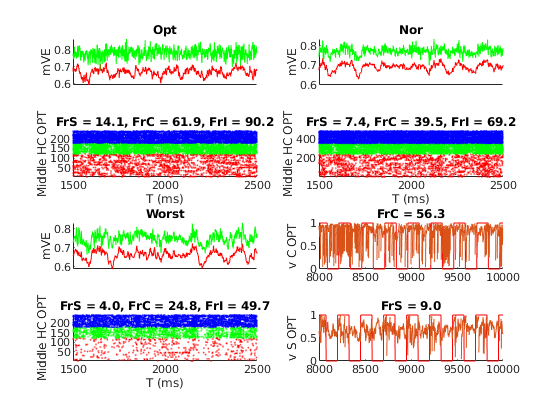

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1.25*n_S_HC & NnS.X<=1.75*n_S_HC;
MidRowS = NnS.Y>=1.25*n_S_HC & NnS.Y<=1.75*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1.25*n_C_HC & NnC.X<=1.75*n_C_HC;
MidRowC = NnC.Y>=1.25*n_C_HC & NnC.Y<=1.75*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

SOpt = find(OptE & ~EcplxInd);
scatterSOpt = find(ismember(SpE(:,1), SOpt));
[~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);

COpt = find(OptE & EcplxInd);
scatterCOpt = find(ismember(SpE(:,1), COpt));
[~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [1500 2500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');  
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');  
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');  
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);